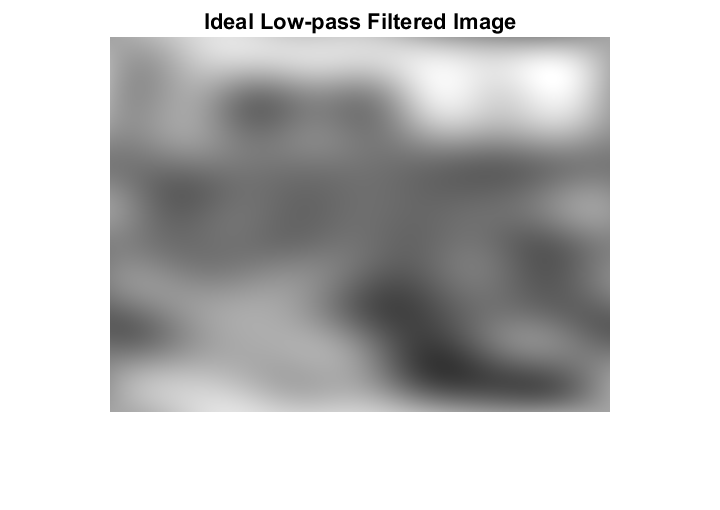

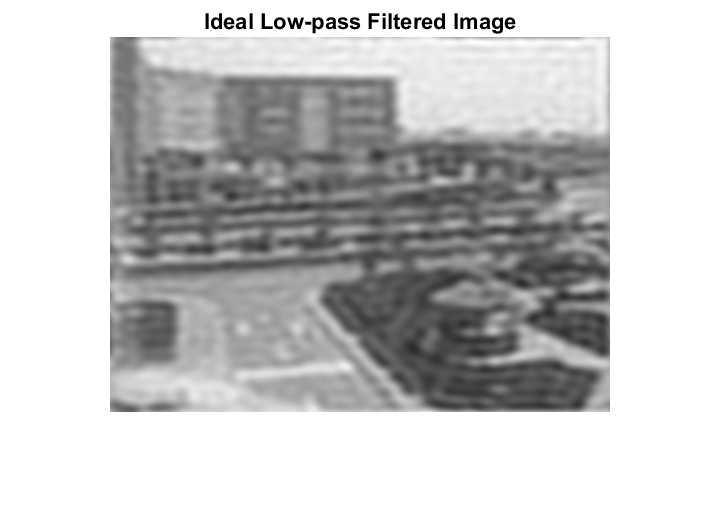

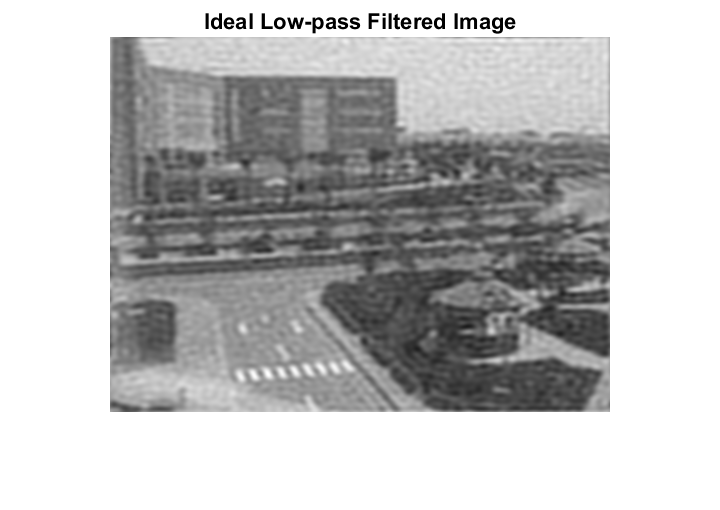

clear;
guc = imread('GUC.jpg');
moon = imread('Moon.jpg');

% Apply ILPF
lp_filter(guc, 'Ideal LP', 30);

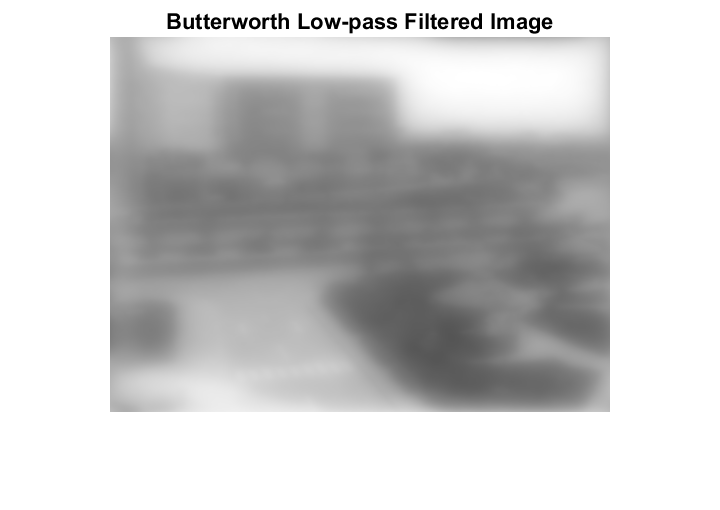

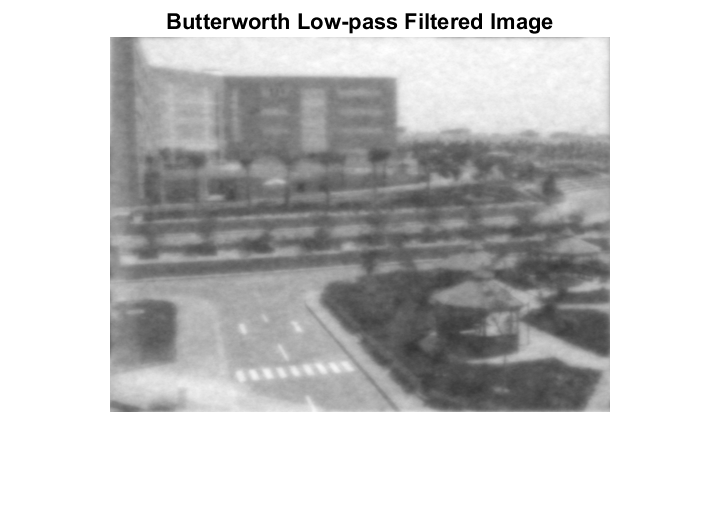

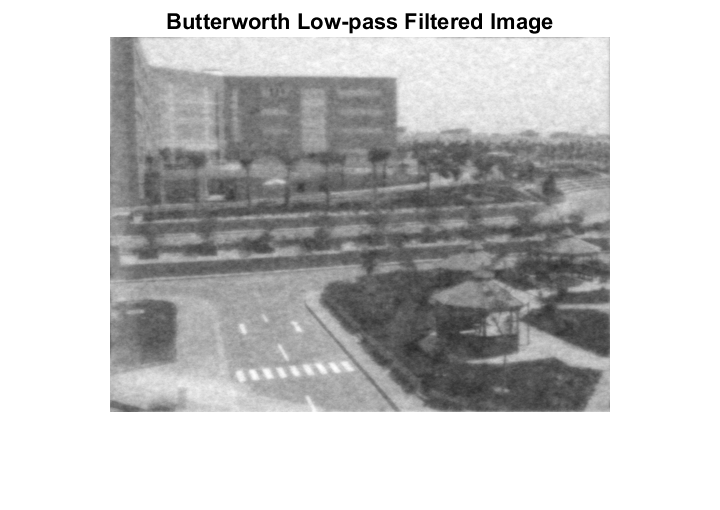


% Apply BLPF
lp_filter(guc, 'Butterworth LP', 30);

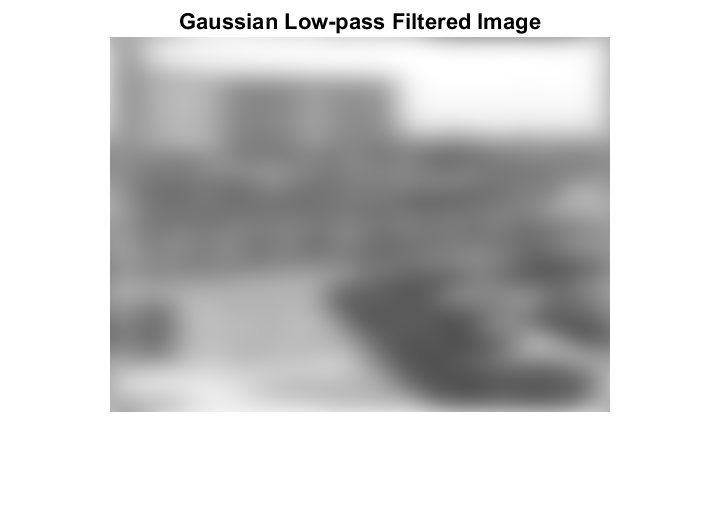

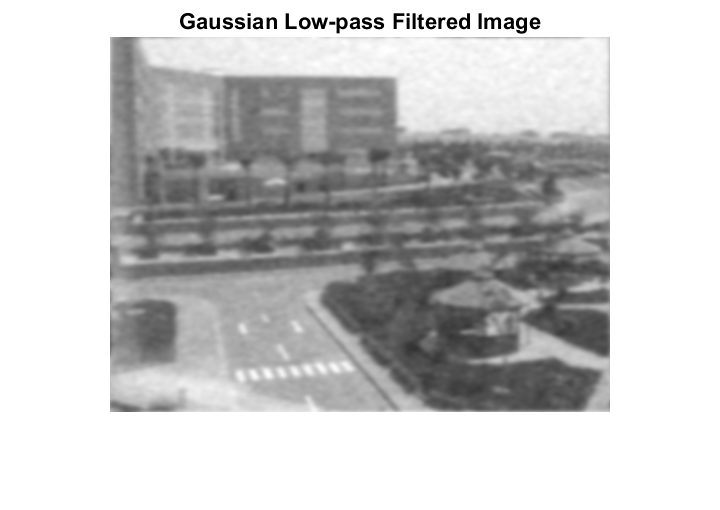

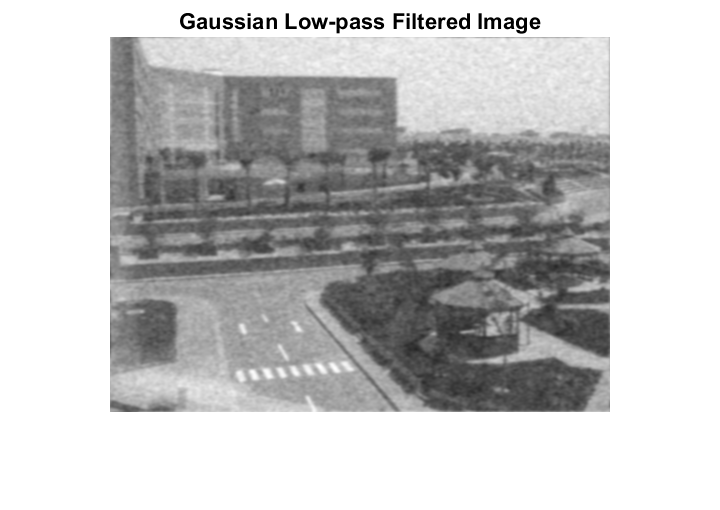


% Apply GLPF
lp_filter(guc, 'Gaussian LP', 30);

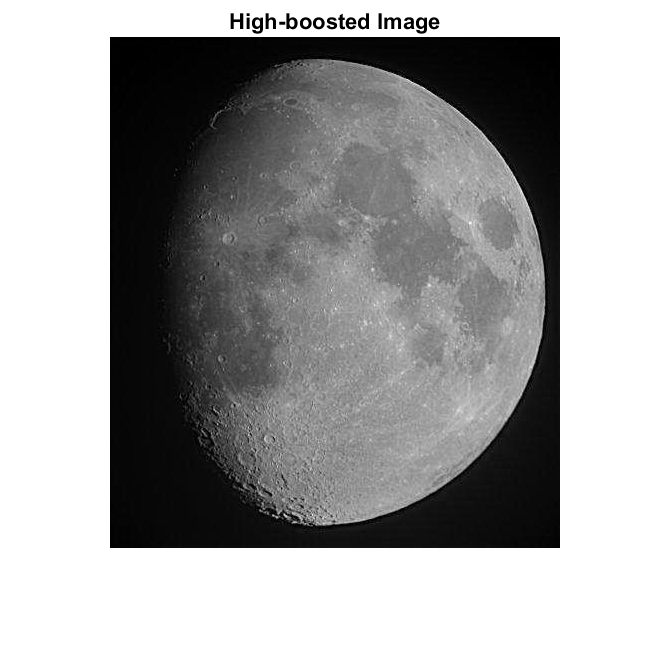


% Apply High-Boost
hb_filter(moon, 1, 50, 1.5);

# External Functions

function lp_filter(img, filter_type, d)
    % 1-FFT
    % 2-Low Pass Filter 
    % 3-Multiply Filter by FFT
    % 4-Inverse FFT
    
F = fftshift(fft2(img));

switch filter_type
    
    case 'Ideal LP'        
        [l,w] = size(img);
        [x,y] = meshgrid(-w/2:w/2-1, -l/2:l/2-1);
        D = sqrt(x.^2 + y.^2);
        H = D < d;
        
        G = H.*F;        
        g = ift(G);
        figure; imshow(g)
        title('Ideal Low-pass Filtered Image')
        imwrite(g, strcat(inputname(1), '_ILPF_', int2str(d), '.jpg'))
        
        
    case 'Butterworth LP'
        n = 1;
        [l,w] = size(img);
        [x,y] = meshgrid(-w/2:w/2-1, -l/2:l/2-1);
        D = sqrt(x.^2 + y.^2);
        H = 1./(1 + ((D/d).^(2*n)));
        
        G = H.*F;        
        g = ift(G);
        figure; imshow(g)
        title('Butterworth Low-pass Filtered Image')
        imwrite(g, strcat(inputname(1), '_BLPF_', int2str(d), '.jpg'))
        
    case 'Gaussian LP'
        [l,w] = size(img);
        [x,y] = meshgrid(-w/2:w/2-1, -l/2:l/2-1);
        D = sqrt(x.^2 + y.^2);
        H = exp(-(D.^2) ./ (2*d^2));
        
        G = H.*F;        
        g = ift(G);
        figure; imshow(g)
        title('Gaussian Low-pass Filtered Image')
        imwrite(g, strcat(inputname(1), '_GLPF_', int2str(d), '.jpg'))
end

end

function hb_filter(img, n, d, A)
    % 1-FFT
    % 2-High Boost Filter 
    % 3-Multiply Filter by FFT
    % 4-Inverse FFT

F = fftshift(fft2(img));

[l,w] = size(img);
[x,y] = meshgrid(-w/2:w/2-1, -l/2:l/2-1);
D = sqrt(x.^2 + y.^2);
H_hp = 1./(1 + ((d./D).^(2*n)));

I = ones(l,w);
H_hb = (I*A - I) + H_hp;

G = H_hb.*F;
g = ift(G);
figure; imshow(g);
title('High-boosted Image')
imwrite(g, strcat(inputname(1), '_HB_', int2str(n), '.jpg'))

end

function f = ift(G)
    % Inverse FFT
    
g = ifft2(G);
f = abs(g);
f = f / max(max(f));

end